Evaluate the double integrals

- $\int \int$(1+4xy)dxdy

syms x y
f=1+4*x*y

$$f = 4\,x\,y+1$$

int(int(f,x,0,1),y,1,3)

$$ans = 10$$

2. $\int_0^1 \int_x^{2-x} \left(x^2 -y\right)$dydx

syms x y
f=x^2-y

$$f = x^{2}-y$$

int(int(f,y,x,2-x),x,0,1)

$$ans = -\frac{5}{6}$$

3.$\int_0^{\frac{\pi }{2}} \int_0^{\cos \theta } e^{\sin \theta }$drd$\theta$

syms r theta
f = exp(sin(theta))

$$f = {\mathrm{e}}^{\sin\left(\theta \right)}$$

int(int(f,r,0,cos(theta)),0,pi/2)

$$ans = \mathrm{e}-1$$

syms x y
f=(x*y^2)/(x^2+1)

$$f = \frac{x\,y^{2}}{x^{2}+1}$$

int(int(f,x,0,1),y,-3,3)

$$ans = \log\left(512\right)$$

Jacobian

syms r theta
a=jacobian([r*cos(theta),r*sin(theta)],[r,theta])

$$a = \left(\begin{array}{cc} \cos\left(\theta \right) & -r\,\sin\left(\theta \right)\\ \sin\left(\theta \right) & r\,\cos\left(\theta \right) \end{array}\right)$$

simplify(det(a))

$$ans = r$$

$\int_0^1 \int_0^{\sqrt{1-x^2 }} e^{\left({x^2 +y^2 } \right)}$dydx=$\int_{\theta =0}^{\theta =\frac{\pi }{2}} \int_{r=0}^{r=1} e^{\left(r^2 \right)}$rdrd$\theta$

syms x y r theta
f=exp(x^2+y^2)

$$f = {\mathrm{e}}^{x^{2}+y^{2}}$$

fpolar=simplify(subs(f,[x,y],[r*cos(theta),r*sin(theta)]))

$$fpolar = {\mathrm{e}}^{r^{2}}$$

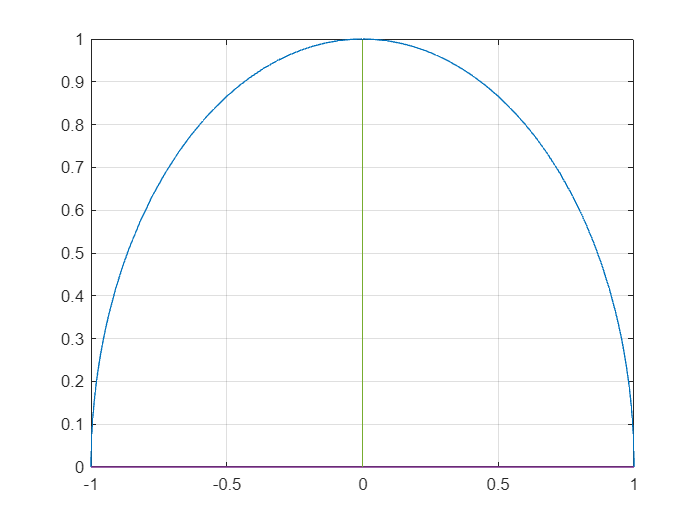

%for plotting the region
fplot(sqrt(1-x^2))
hold on
plot([-1,1],[0,0])
plot([0,0],[0,1])
hold off
grid on

integrand=r*fpolar

$$integrand = r\,{\mathrm{e}}^{r^{2}}$$

int(int(integrand,r,0,1),theta,0,pi/2)

$$ans = \frac{\pi \,\left(\mathrm{e}-1\right)}{4}$$

Use double integrals to find the area of the region

i) area bounde by the parabola y=$x^2$ and the line y=2x+3

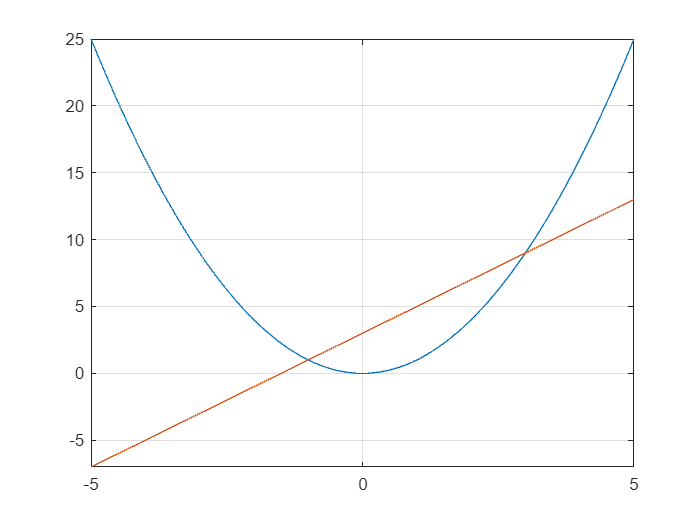

syms x y
par=x^2;
line=2*x+3;
fplot(par)
hold on
fplot(line)
grid on
hold off

xvalues=solve(par==line)

$$xvalues = \left(\begin{array}{c} -1\\ 3 \end{array}\right)$$

%points of intersection are (-1,10 and(3,9)
int(int(1,y,x^2,2*x+3),x,-1,3)

$$ans = \frac{32}{3}$$

smaller the area bounded by the circle $x^2$+$y^2$=9 and line  x+y=3

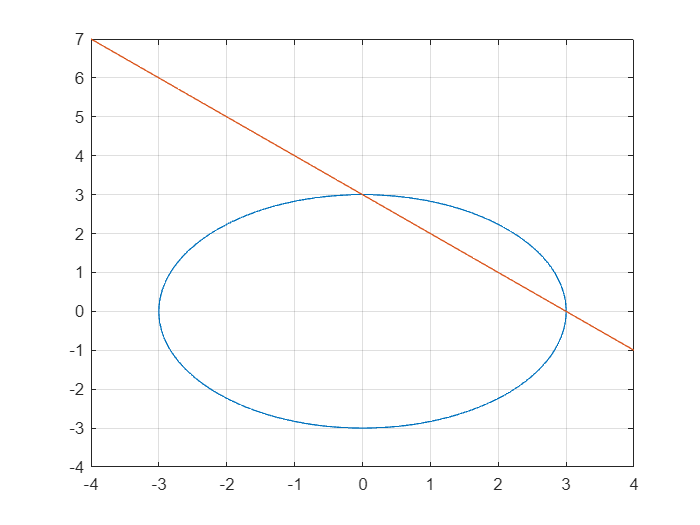

syms x y
fimplicit(x^2+y^2-9,[-4,4])
hold on
fplot(3-x,[-4,4])
grid on
hold off

int(int(1,y,3-x,sqrt(9-x^2)),x,0,3)

$$ans = \frac{9\,\pi }{4}-\frac{9}{2}$$